# MATLAB LAB #0 - Part 1

**Connecting to the database**

This is an example script to introduce you to MATLAB. You will make some guided edits, run the script, print the output to pdf, and submit them as proof of your completion. 

This example will help ensure that you can connect to the database, uploading a single datapoint and downloading the class dataset. Since you're reading this, you must have figured out how to access and use MATLAB which is the most important thing. Most MATLAB assignments will have an assignment template/guide like this to handle elements beyond what you need to be able to know. 

A MATLAB program is typically written as script files, a .m file type. This is a what's called a MATLAB livescript, which allows for more rich text format details like what your reading now as well as sections. I can also include input fields, which you'll see below, to help with data entry. I will use livescripts for examples and lessons at times. You will be developing  regular scripts so you don't need to know how to create livescripts, just follow along and use them. 

## Before you begin, have everything you'll need

### Software

You will need some custom MATLAB functions and java resource to be able to interact with the lab-in-a-box and the database we use for consolidating data. Since you're looking at this, it's likely you've already downloaded them but just to be sure, you should have the following shown in your *Current Folder* on the left hand side of your user interface.

- ML0H1_XXXXX.mlx (The file you're currently working in)

- mysql-connector-jave-8.0.25.jar

- ML0H1_DB.m

- MLDBConn.p

THESE MUST BE INCLUDED IN YOUR **Current Folder with the MATLAB script **to function properly, as shown here:

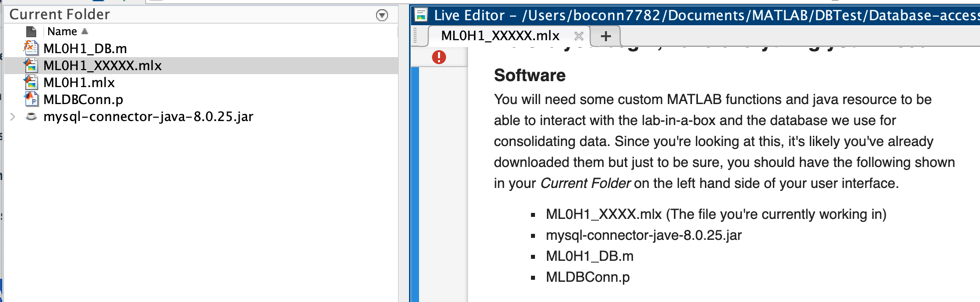

Here's more details on what each of these are:

### mysql-connector-jave-8.0.25.jar

This is a JAVA resource that MATLAB needs to create that database connection and will be used by every script that needs to access the database. 

### ML0H1_DB.m

Support functions with the suffix **_DB** will be for uploading data to the database and downloading a dataset of the class data. You would provide it with your data to be added to the database table and it will return a dataset that you'll use for the rest of the assignment. That dataset would be either all or a subset of the data collected by the rest of the class. 

### MLDBConn.p

This is a connection function that creates the link with the database. It is a p file because that's a type of MATLAB file that is pre-parsed, meaning the data is already converted and therefore not visible to you. This is to protect the security of the database as best I can. 

If you have any further questions about any provided custom functions, you can run the command `help <function file name> `to get more information about that function. For instance, copy this command and run it in the Command Window below:

# MATLAB LAB #0 - Homework Part 1

This MATLAB Livescript will walk you through creating your first program and running it. It's primary goal is to ensure you can make the database connection that will be used in many MATLAB assignments as well as upload data and download a dataset. It will also walk you through using that dataset as a simple first program.

## Part 1: Your First MATLAB Script

This is prepared as a MATLAB Live Script. Anything in a grey box is code that will actually run. The text with white backgrounds is instruction, guidance, or for reference.

### Step 1: Save Early and Save Often

Save your own copy of this live script using the *Save As* option under the save icon in the Live Editor tab of the Ribbon. Name the file using the given naming convention ... _ <First Initial><First 4 letters of your last name> replacing the < > with the content described within. For instance, Prof. O'Connell would use `ML0HP1_BOCON.mlx`. You will later save this as a regular matlab script for submission but it's good to have your own version to work on and the older version still available in case you need to go back to it. I often have several versions of a script before I finalize it and delete the old ones.  

### Step 1: Create a Title Block

At the start of every assignment you should fill out a code header to identify your program, distinguish yourself as the author and include any details for anyone who will later review your code. This is done in **comments **which are non-code elements included in a program for reference, dentoed by starting the line with `%`. An example title block is shown below. Anything enclosed in < > is a descriptor of what you should replace it with, including replacing the < >. For instance, `<First Initial>.<Last Name> `for Prof. O'Connell would become `B.O'Connell`. Replace the descriptors below with your own information.

% MATLAB Lab #0 Homework Part 1
% <First Initial>.<Last Name>
% <Date of creation>
% <Name of Script - You have some freedom to decide this>
% <Description of what the program will do. In other assignmnents,...
% this will be more apparent up front. In this case, you're welcome to...
% come back to this after going through the rest of this and edit it> 


That title block was created in a coment block. The % at the beginning of the line indicates that these are comments and MATLAB will not interpret them as any code. 

### Step 2: A Clean Slate

The following commands clear the workspace and command window. This is a common practice for most scripts to ensure you don't have extranious variables that may conflict with your script. 


clc;    % Clears the workspace
clear;  % Clears the command window


The blue line below the following image denotes the end of a section. To run all of the code, you would use the **Run** command. To just run the code in your current section, use **Run Section** but some of it may be dependent on previous code so make sure you've run those prior sections as well. 

In a Livescript, you'll usually just run each section after you've filled in the blanks or inputted the requested information, the run the whole script at the end. 

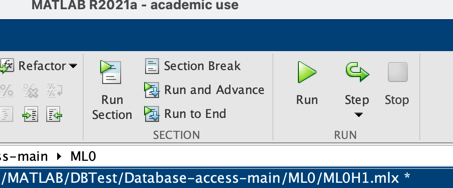

Run this section before continuing

#### STEP 3: Collect some data

For this first example, we're just going to collect some class user data. Future assignments will collect things like UV light levels, reaction times, signal noise, etc. Normally there would be some hardware associated but since we haven't distributed anything, you'll just input it manually. 

#### User Data 

Fill out the data entry fields in the grey code blocks below: 

**NOTE: **The information below will be used for cross-referencing against future assignments. In some cases, the dataset will only take the latest upload from each student so we need an identifier to be able to sort the data, in this case it's your NU email address. All dataset exports will be anonymized so the identifier won't be associated with any specific datapoint. 

Enter your Northeastern Email address:

% Some labs with a database element will require this as a unique
% identifier of the supplier of the data point
email = "rogers.s@northeastern.edu"

Enter your given and family name:

ForeName = "Steve" % Fore, First, or Given Name
SurName =  "Rogers" % Sur, Last, or Family Name

#### Assignment Data

Now lets' collect some very, very important data that we'll use in our analysis. 

Select your favorite Avenger from the Marvel Cinematic Universe:

Fav_Avenger = "Captain America"

Run this section before continuing

### Step 4: Data Upload/Download

You will be provided a support function, `ML0H1_DB()`, to handle the database connection. This will upload your data point and then return the dataset for the rest of the assignment. The details will be assignment specific but it will always take the individual datapoint as an input and output the full dataset. What that all means will become apparent as we progress but for now, the code is already provided below.

This next line of code uploads your data and download the assignment dataset:

X = ML0H1_DB(email, ForeName, SurName, Fav_Avenger);

**Note:** If you get a warning, which you would after your first run of this script, it's fine to submit with the warning. You will see warnings at times when data is manipulated or updated because that's a best practice when altering any user inputs or deviating from any likely user assumptions. In this case, it warns you that you've already submitted something so it's overwritting your previous submission instead of adding a new one.

The support function will also output whatever dataset you would need for the rest of the assignment. Right now, that is stored in the variable `X`.

Run this section before continuing

### Step 5: Your First Program

Now that you've uploaded and recieved data, it's time for you to actually do some MATLAB programming. Typically, you would take the concepts and commands from the lesson and use those to analyze, assess, and visualize the data. Since you currently have not had any lessons, the code is provided and there's some instructions so you can make some contributions. You do not need to understand the individual commands and the code overall, you are welcome to read the comments to gain a high level understanding. 

% Create numeric version of the Favorite Avenger
% list (X.Avenger) for a histogram
A = ["No Opinion", "Captain America", "Iron Man", ...
    "Thor Odinson", "Hulk", "Black Widow", ...
    "Hawkeye", "War Machine", "Vision", ...
    "Scarlet Witch", "Falcon", "Spider-Man", ...
    "Ant-Man", "Nebula", "Rocket","Captain Marvel"];
Ac(1:length(X.Avenger)) = 0;

for i = [1:length(X.Avenger)]
    for j = [1:length(A)]
        if X.Avenger(i) == A(j)
            Ac(i) = j;
        end
    end
end

C = categorical(Ac,[1:length(A)],A);


We now have some organized categorical data (It's not expected that you know what that means.) stored in the Variable C. We want to present that infromation as a Histogram. 

Take a wild guess what command would be used to create a histogram of the dataset C 

(Hint: It's `histogram(C); `MATLAB commands tend to be pretty spot on )

% Create a histogram showing the class's favorites regarding Avengers.



% If you're not seeing a histogram off to the side, 
% try entering this code above this line: histogram(C)

If you are quick to work on this, you are likely only to have a few entries. That's fine. 

Save a copy of this livescript as a normal script, as a .m file. It will have all of the code you edited as well all of my descriptions above as comments.

Sace a copy of your histogram as a pdf. You can either print to pdf or select save as and use pdf as the file format. 

You will submit these as part of this assignment. The instructions for that are back in the Top Hat document. 